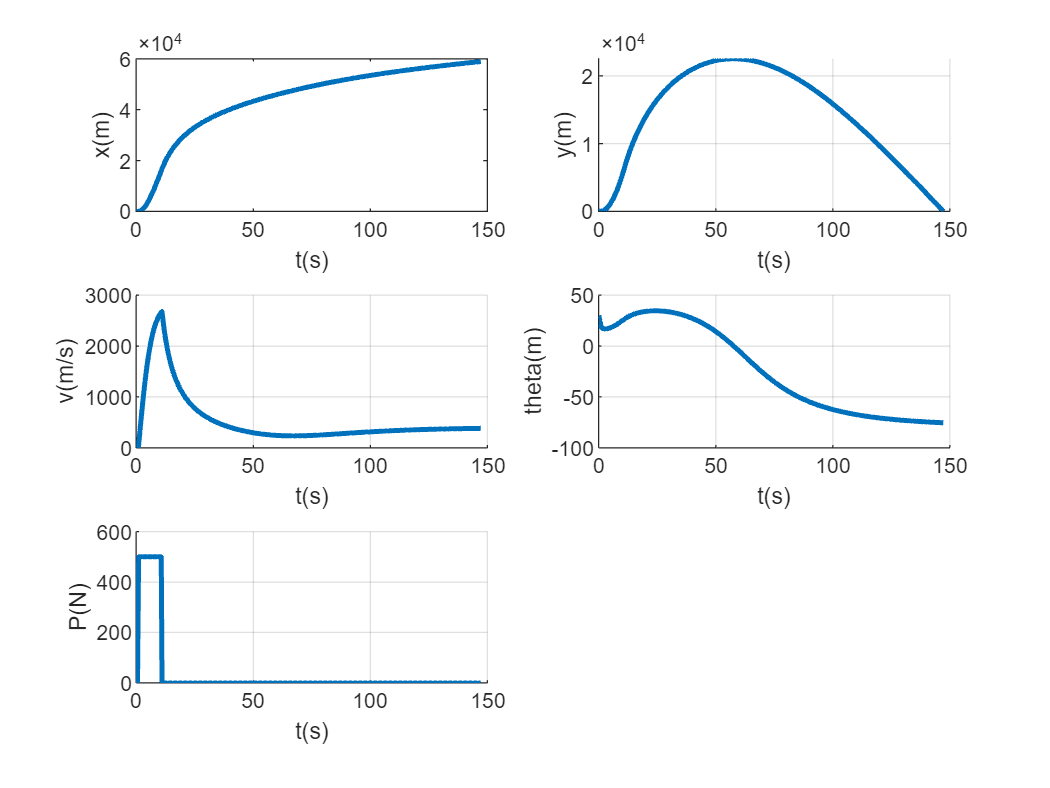

%% 参数设置
close all,clear,clc,

global m g rho S Cq Cy alpha P
m = 100;
g = 9.8;
rho = 1.225;
S = 0.01;
Cq = 1;
Cy = 0.2;
alpha = 3/180*pi;
P = 500;

v0 = 50;
theta0 = 30/180*pi;
x = 0;
y = 0;
v = v0;
theta = theta0;
state = [x; y; v; theta0];
stateout = state;

dt = 0.005;
t = 0;
tout = t;

T = 10;
ton = 1; %力矩作用时间起始
toff = ton + T; %力矩作用时间结束

F = 500;
Pout = [];
%% 仿真
while y >= 0
    if or(t < ton, t > toff) == 1
        P = 0;
    else
        P = F;
    end
    Pout = [Pout, P];
    ke1 = stateequation(t, state, P);
    ke2 = stateequation(t+0.5*dt, state+0.5*ke1*dt, P);
    ke3 = stateequation(t+0.5*dt, state+0.5*ke2*dt, P);
    ke4 = stateequation(t+dt, state+ke3*dt, P);
    state = state + 1/6*(ke1 + 2*ke2 + 2*ke3 + ke4)*dt;
    stateout = [stateout, state];

    y = state(2);
    t = t + dt;
    tout = [tout, t];
end

xout = stateout(1, :);
yout = stateout(2, :);
vout = stateout(3, :);
thetaout = stateout(4, :);
Pout = [Pout, Pout(end)];
%% 绘图
figure(1);
hold on;grid on;
subplot(3,2,1);
plot(tout, xout, 'LineWidth', 2);
xlabel('t(s)');ylabel('x(m)');

subplot(3,2,2);
hold on;grid on;
plot(tout, yout, 'LineWidth', 2);
xlabel('t(s)');ylabel('y(m)');

subplot(3,2,3);
hold on;grid on;
plot(tout, vout, 'LineWidth', 2);
xlabel('t(s)');ylabel('v(m/s)');

subplot(3,2,4);
hold on;grid on;
plot(tout, rad2deg(thetaout), 'LineWidth', 2);
xlabel('t(s)');ylabel('theta(m)');
grid on;

subplot(3,2,5);
hold on;grid on;
plot(tout, Pout, 'LineWidth', 2);
xlabel('t(s)');ylabel('P(N)');

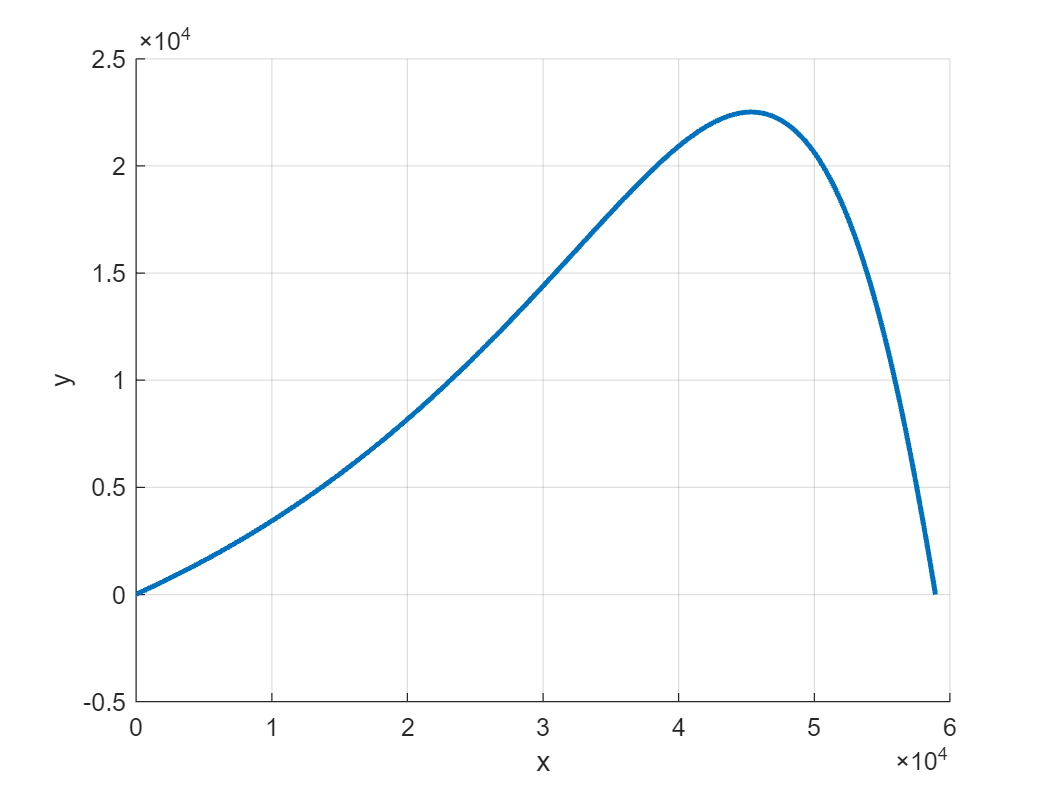


figure(2);
hold on;grid on;
plot(xout,yout,"LineWidth",2);
xlabel('x');ylabel('y');

function statedot=stateequation(t,state, P)
global m g rho S Cq Cy alpha
% state = [x,y,v,theta];
x = state(1);
y = state(2);
v = state(3);
theta = state(4);

xdot = v*cos(theta);
ydot = v*sin(theta);
Q = 0.5*rho*v^2*S*Cq;
Y = 0.5*rho*v^2*S*Cy;
vdot = -g*sin(theta) - Q/m + P*cos(alpha);
thetadot = 1/v*(-g*cos(theta) + Y/m + P*sin(alpha)/m);

statedot = [xdot; ydot; vdot; thetadot];
end